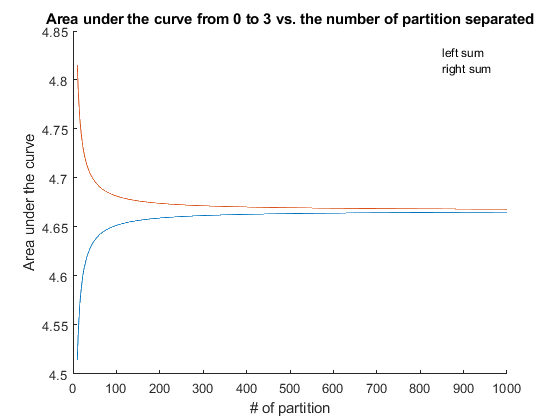

upperB=3;
lowerB=0;
lowerBN=10;
upperBN=1000;
listN=(lowerBN:upperBN);
listSumR=(lowerBN:upperBN);
listSumL=(lowerBN:upperBN);
%right hand
for n =listN
    sum=0;
    for i =1:n
        sum=sum+(sqrt((lowerB)+i*(upperB-lowerB)/n+1))*((upperB-lowerB)/n);
    end
    listSumR(n-9)=sum;
end
%left hand
for n =listN
    sum=0;
    for i =0:n-1
        sum=sum+(sqrt((lowerB)+i*(upperB-lowerB)/n+1))*((upperB-lowerB)/n);
    end
    listSumL(n-9)=sum;
end
hold on
plot(listN, listSumL,'-')
plot(listN, listSumR,'-')
title("Area under the curve from 0 to 3 vs. the number of partition separated")
legend("left sum", "right sum")
ylabel("Area under the curve")
xlabel("# of partition")